% This script demonstrates how to compute a terminal region for the
% random double integrator benchmark using the linSysApproach algorithm

% load system parameter
Param = param_doubleIntegrator();
Param = rmfield(Param,'R0');

% define algorithm settings
Opts = [];

Opts.Tdomain = interval(-ones(2,1),ones(2,1));  % seach domain
Opts.timeStep = 0.1;                            % time step size
Opts.N = 30;                                    % number of time steps
Opts.Q = eye(2);                                % state weighting matrix
Opts.R = eye(1);                                % input weighting matrix
Opts.genMethod = 'sampling2D';                  % generator selection
Opts.costFun = 'sum';                           % cost fun. opt. problem

% compute terminal region
clock = tic;
T = computeTerminalRegion('doubleIntegrator','zonoLinSys',Param,Opts);

Computing safe terminal set (phase 1) ...
Computing safe inital set (phase 2) ...
Succesfully computed the terminal region.


tComp = toc(clock);

disp(['Computation time: ',num2str(tComp),'s']);

Computation time: 36.725s


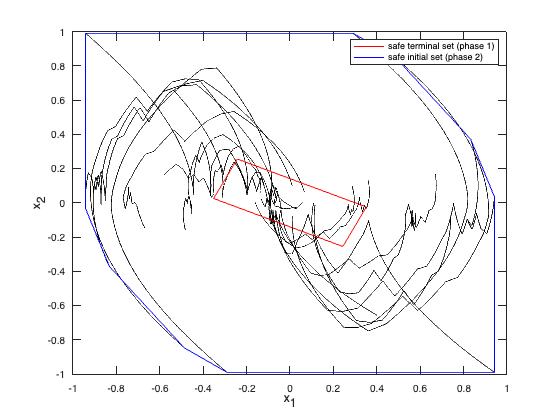


% simulate terminal region controller
tFinal = 10;
res = simulateRandom(T,tFinal);

% visualization
figure; hold on; box on;
plotSimulation(res,[1,2],'k');
h1 = plot(T.set,[1,2],'b');
h2 = plot(T.termSet,[1,2],'r');
legend([h2,h1],'safe terminal set (phase 1)','safe initial set (phase 2)');
xlabel('x_1'); ylabel('x_2');